clear all, close all, clc

## Example 5.1

### (b)

Given system,

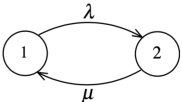

syms L mu t
M = [-L, mu; L, -mu]      % transition rate matrix, for availability

$$M = \left(\begin{array}{cc} -L & \mu \\ L & -\mu \end{array}\right)$$

### (c)

Now, from equation-19, we get


$$P_n {\left(t\right)}=\delta_{n1} +M_{n1} t+\sum_{j,1}^N \frac{M_{nj} M_{j1} t^2 }{2!}+\ldots$$


For, transitioning from state n to m

dl_nm = 1;      % n = m, dl = 1
Nu = 1;         % no. of upstates


$$A{\left(t\right)}=\sum_{n=1}^{N_u } P_n \left(t\right)$$


P_nS = 0;           % intialize term at n-loop
for n=1:1:Nu
    M_AjS = 0;       % initialize term at j-loop
    for j = 1:1:Nu

            
$$\sum_{j,1}^N \frac{M_{nj} M_{j1} t^2 }{2!}$$


            fc2 = factorial(2);
        M_Aj = M(n,j)*M(j,1)*t^2 /fc2;       % jth term
        M_AjS = M_AjS + M_Aj; 
    end 
        M_AjS           % summed value after j-loop

           
$$\delta_{n1} +M_{n1} t+\sum_{j,1}^N \frac{M_{nj} M_{j1} t^2 }{2!}$$


    P_n = dl_nm + M(n,1)*t + M_Aj;
    P_nS = P_n + P_nS;
end

$$M\_AjS = \frac{L^{2}\,t^{2}}{2}$$

A_t = P_nS         % availability

$$A\_t = \frac{L^{2}\,t^{2}}{2}-L\,t+1$$

### (d)

Now, let's build an Matrix for getting eigenvalues-


$$\mathit{\mathbf{E}}=|S\;\mathit{\mathbf{I}}-\mathit{\mathbf{M}}|$$


syms s
I = eye(2);         % identity matrix
E = s*I - M         % eigenvalue matrix

$$E = \left(\begin{array}{cc} L+s & -\mu \\ -L & \mu +s \end{array}\right)$$

Now, let's find the determinant and eigenvalues

Dt = det(E)             % determinant

$$Dt = L\,s+\mu \,s+s^{2}$$

Now, let's solve it to find the Eigenvacture

S = solve(Dt, s)     % solution vector

$$S = \left(\begin{array}{c} 0\\ -L-\mu \end{array}\right)$$

Now, equation 25 gives us the follows-


$$P_n {\left(s\right)}=\frac{cof{{\left(s\bar{I\;} -\bar{\;M} \right)}}_n^T }{\Delta }$$


Here, $\Delta ={\left(s-s_1 \right)}{\left(s-s_2 \right)}\ldots\left(s-s_N \right)=$ Determinant

So, let's find the $\Delta \;$    [Not, necessary]

Del = 1;            % initialize
n = length(S);      % length of solve-vector
for i=1:1:n
    Del = Del*(s - S(i));
end
Del             % show exp'

$$Del = s\,\left(L+\mu +s\right)$$

Now, let's find the P_1(s)-

E_T = transpose(E);         % transpose the eigen matrix
CF_1 = cofact(E_T, 1,1)     % cofactor of E_T at (1,1)

$$CF\_1 = \mu +s$$

P_s1 = CF_1 /Dt 

$$P\_s1 = \frac{\mu +s}{L\,s+\mu \,s+s^{2}}$$

Let's expand it into polynomial form

P_s1 = expand(P_s1);         % expanding into polynomial

And that's the availability of the systsem, by dint of inverse Laplace transform-

A_t = ilaplace(P_s1, t)     % t- laplace variable

$$A\_t = \frac{\mu }{L+\mu }+\frac{L\,{\mathrm{e}}^{-t\,\left(L+\mu \right)}}{L+\mu }$$

### (e)

Let's place the following value-

mu = 0;

Then, we get-

M = eval(M)         % evaluating for mu, tr-rate matrix

$$M = \left(\begin{array}{cc} -L & 0\\ L & 0 \end{array}\right)$$

A_t1 = eval(A_t)    

$$A\_t1 = {\mathrm{e}}^{-L\,t}$$

The above is the reliability of the system. So-

R_t = A_t1;         % reliability

Now, let's plot them for different values of associated parameters

L = 1e-2;                       % tr-rate, 1 to 2; h^-1
mu = 0.5*1e-2;                  % tr-rate, 2 to 1; slower; h^-1
    t0 = 0; tn = 500;           % #input
t = linspace(t0, tn, 101);      % hours
A_tv = eval(A_t);               % evaluated for given values
R_tv = eval(R_t);

Now, plot 'em

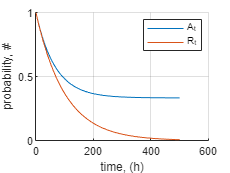

figure()
grid on, hold on
plot(t, A_tv, 'DisplayName', 'A_t')
plot(t, R_tv, 'DisplayName', 'R_t')
legend
xlabel('time, (h)')
ylabel('probability, #')

## Example 5.2b

The states are

M = [11 12 13 14;...
     21 22 23 24;...
     31 32 33 34;...
     41 42 43 44];      % element numbers

And, in symbols, that would be-

syms L1 L2 mu1 mu2
M = [-(L1+L2), mu1, mu2, 0;...
      L1, -(L2+mu1), 0, mu2; ...
      L2, 0, -(L1+mu2), mu1; ...
      0, L2, L1, -(mu1+mu2)]

$$M = \left(\begin{array}{cccc} -L_{1}-L_{2} & \mu_{1} & \mu_{2} & 0\\ L_{1} & -L_{2}-\mu_{1} & 0 & \mu_{2}\\ L_{2} & 0 & -L_{1}-\mu_{2} & \mu_{1}\\ 0 & L_{2} & L_{1} & -\mu_{1}-\mu_{2} \end{array}\right)$$

## Example 5.5

The states are

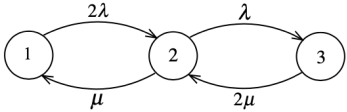     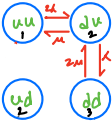

Here, let's make the transition matrix-

syms L mu
M = [-2*L,  mu,     0;...
     2*L, -(L+mu), 2*mu;...
     0,    L,      -2*mu; ]

$$M = \left(\begin{array}{ccc} -2\,L & \mu & 0\\ 2\,L & -L-\mu & 2\,\mu \\ 0 & L & -2\,\mu \end{array}\right)$$

Then, for steady state, replace the first row with 1. So-

M(1,:) = ones();        % replacing with ones
M_ss = M               % Steady statte tr' matrix

$$M\_ss = \left(\begin{array}{ccc} 1 & 1 & 1\\ 2\,L & -L-\mu & 2\,\mu \\ 0 & L & -2\,\mu \end{array}\right)$$

Then, transpose the matrix

M_ssT = M_ss'            % transpose

$$M\_ssT = \left(\begin{array}{ccc} 1 & 2\,\bar{L} & 0\\ 1 & -\bar{L}-\bar{\mu } & \bar{L}\\ 1 & 2\,\bar{\mu } & -2\,\bar{\mu } \end{array}\right)$$

Now, probability of system being at state n- at steady state (SS) is-


$$P_n {\left(\infty \right)}=\frac{cof{{\left({{\mathit{\mathbf{M}}}^T }_{A\infty } \ \right)}}_n^{\;} }{\left|{\mathit{\mathbf{M}}}_{A\infty } \right|}$$


Now, as state 3 is being the only failed state-

Dt = det(M_ssT);              % determinant
Dt = simplify(Dt)

$$Dt = 2\,{\left(\bar{L}+\bar{\mu }\right)}^{2}$$

CF_31 = cofact(M_ssT, 3,1)   % defining the cofactor

$$CF\_31 = 2\,{\left(\bar{L}\right)}^{2}$$

So, we have-

P_3_ss = CF_31 /Dt          % 

$$P\_3\_ss = \frac{{\left(\bar{L}\right)}^{2}}{{\left(\bar{L}+\bar{\mu }\right)}^{2}}$$

A_ss = 1- P_3_ss            % SS availability

$$A\_ss = 1-\frac{{\left(\bar{L}\right)}^{2}}{{\left(\bar{L}+\bar{\mu }\right)}^{2}}$$

In other method, we get-


$$A{\left(\infty \right)}=1-\sum_{N_u +1}^N P_n \left(\infty \right)$$


N= 3;
Nu = 2;         % up-states
    P_3_ssS = 0;                % initializer
for i = 1 :1 :(N-Nu)            % check the criteria
    CF_3 = cofact(M_ssT, 3,i);
    P_3(i) = CF_3/Dt;
    P_3_ssS = P_3(i) + P_3_ssS;
end 
P_3_ssS;                % view the value
A_ss = 1 - P_3_ssS

$$A\_ss = 1-\frac{{\left(\bar{L}\right)}^{2}}{{\left(\bar{L}+\bar{\mu }\right)}^{2}}$$

## Example 5.7

The system goes like-

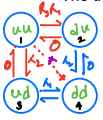 Here, $\lambda_1 -R_s \lambda_1 +\lambda_{2s} -\lambda_2$

The system's transition matrix-

syms L1 L2 L2_s R_sw
    a = - L1 -L2_s;
    b = R_sw*L1;
    c = L1 - R_sw*L1 + L2_s - L2;       % great deal
M_R = [ a,  0,   0,   0; ...
        b, -L2,  0,   0; ...
        L2, 0,  -L1,  0; ...
        c,  L2   L1,  0;];

The system has no repair. So, let's only do the upstate transition matrix. 

M_Ru = [ a,  0,   0; ...
         b, -L2,  0; ...
         L2, 0,  -L1;]

$$M\_Ru = \left(\begin{array}{ccc} -L_{1}-L_{2,s} & 0 & 0\\ L_{1}\,R_{\mathrm{sw}} & -L_{2} & 0\\ L_{2} & 0 & -L_{1} \end{array}\right)$$


dt_M_Ru = det(M_Ru);

Then, we know-


$$K_n =-\frac{{{\left(cof\ M_{Ru}^T \right)}}_{n1} }{\left|{\mathit{\mathbf{M}}}_{Ru} \right|}$$


M_Ru_T = M_Ru';
K_1 = -cofact(M_Ru_T, 1,1) /dt_M_Ru;

$$K\_1 = \frac{\bar{L_{1}}\,\bar{L_{2}}}{L_{1}\,L_{2}\,\left(L_{1}+L_{2,s}\right)}$$

K_2 = -cofact(M_Ru_T, 2,1) /dt_M_Ru;
K_3 = -cofact(M_Ru_T, 3,1) /dt_M_Ru;

So, let's find the MTTF


$$MTTF=\sum_n^{N_u } k_n$$


Nu = 3;
    K_S = 0;
for i = 1:1:Nu
    K(i) = -cofact(M_Ru_T, i,1) /dt_M_Ru;
    K_S = K(i) + K_S;
end

MTTF = K_S

$$MTTF = \frac{{\left(\bar{L_{2}}\right)}^{2}}{L_{1}\,L_{2}\,\left(L_{1}+L_{2,s}\right)}+\frac{\bar{L_{1}}\,\bar{L_{2}}}{L_{1}\,L_{2}\,\left(L_{1}+L_{2,s}\right)}+\frac{{\left(\bar{L_{1}}\right)}^{2}\,\bar{R_{\mathrm{sw}}}}{L_{1}\,L_{2}\,\left(L_{1}+L_{2,s}\right)}$$

MTTF = simplify(MTTF);